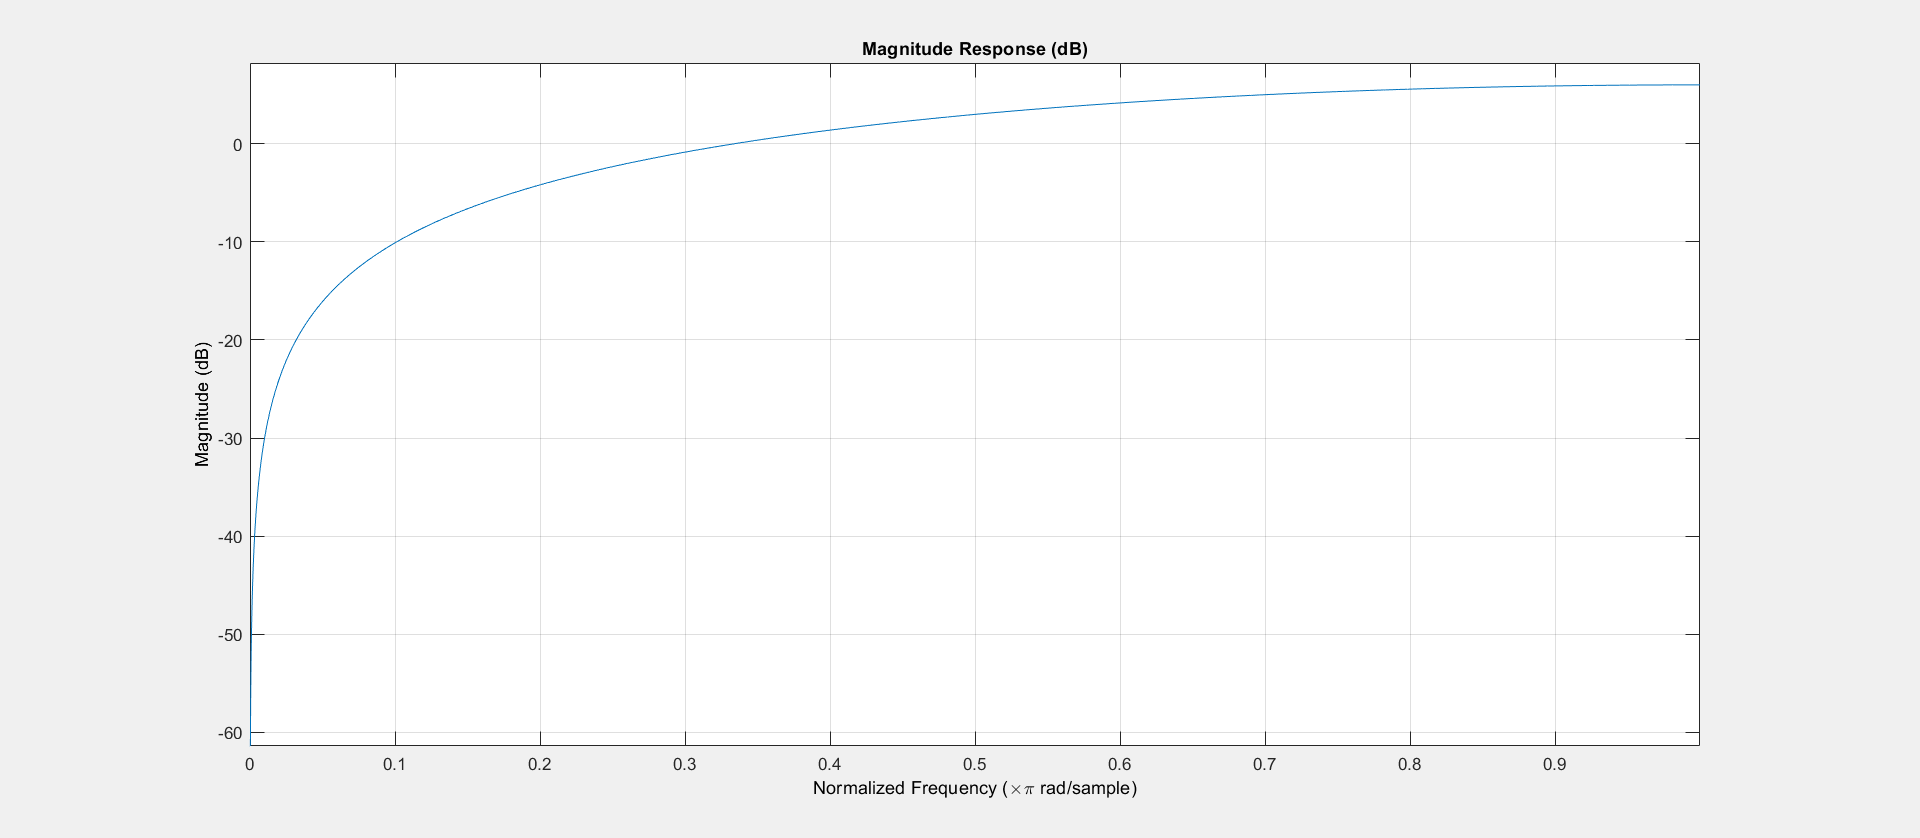

fvtool([1,-1],1)

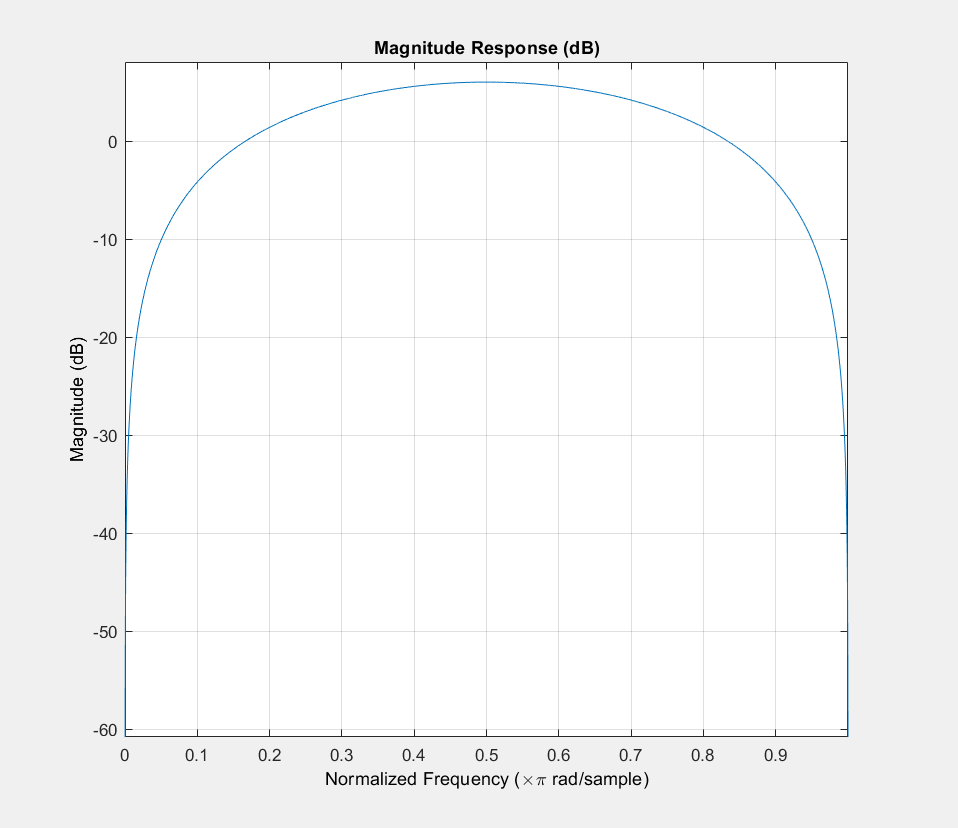

fvtool([1,0,-1],(1))

clear;
clc;
load ECG_rec.mat;

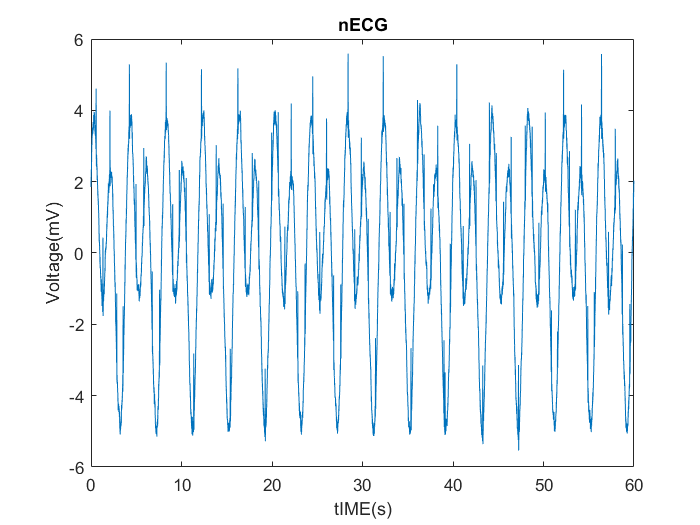

nECG1=awgn(ECG_rec,10,'measured');
t=(0:length(ECG_rec)-1)/128;
EMGt=2*sin(t.*(2*pi/4))+3*sin(t.*pi+pi/4);
nECG=nECG1+EMGt;
plot(t,nECG)
title('nECG')
xlabel('tIME(s)')
ylabel('Voltage(mV)')

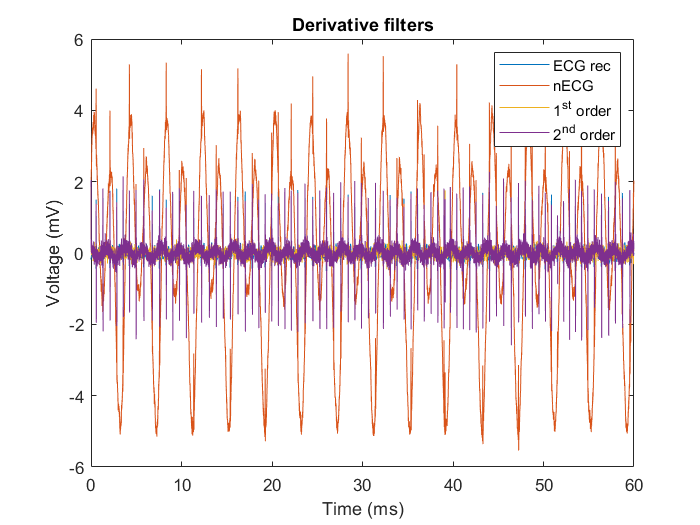

first_filter=filter([1,-1],(1),nECG);
second_filter=filter([1,0,-1],(1),nECG);
plot(t,ECG_rec,t,nECG,t,first_filter,t,second_filter)
xlabel('Time (ms)')
ylabel('Voltage (mV)')
legend('ECG rec','nECG','1^{st} order', '2^{nd} order')
title('Derivative filters')